# Q1

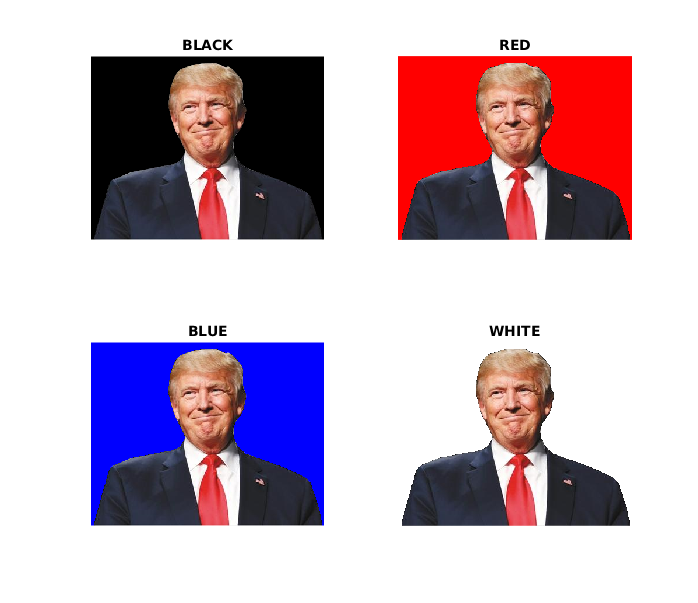

Trump_black = imread('QMQ1.png');
background = imopen(Trump_black, strel('disk', 15));
ind = (background(:,:,1)<=10)&(background(:,:,2)<=10)&(background(:,:,3)<=10);
ind_red = false(size(Trump_black));
ind_red(:,:,1) = ind;
ind_green = false(size(Trump_black));
ind_green(:,:,2) = ind;
ind_blue = false(size(Trump_black));
ind_blue(:,:,3) = ind;
Trump_red = Trump_black; Trump_red(ind_red) = 255;
Trump_blue = Trump_black; Trump_blue(ind_blue) = 255;
Trump_white = Trump_black; Trump_white(ind_red | ind_green | ind_blue) = 255;
subplot(2,2,1)
imshow(Trump_black); title('BLACK');
subplot(2,2,2)
imshow(Trump_red); title('RED');
subplot(2,2,3)
imshow(Trump_blue); title('BLUE');
subplot(2,2,4)
imshow(Trump_white); title('WHITE');

# Q2

芒德布罗集定义为


$$M := \{c \in \mathbb{C}: \{f^n_c(0)\}_{n=0}^{\infty}\text{ is diverge}\}, \text{where, }f^n_c(z)=z^2+c$$


T=240;
for t=1:T
    mandelbrot(1024,100,-0.21503361460851339,0.67999116792639069,exp(-t/10))
    picname=[num2str(t) '.fig'];
    saveas(gcf,picname)
    close
end
for t=1:T
    picname=[num2str(t) '.fig'];
    open(picname)
    frame=getframe(gcf);  
    im=frame2im(frame);
    [I,map]=rgb2ind(im,20);          
    if t==1
        imwrite(I,map,'mandelbrot.gif','gif', 'Loopcount',inf,'DelayTime',1/24);
    elseif t==T
        imwrite(I,map,'mandelbrot.gif','gif','WriteMode','append','DelayTime',1/24);
    else
        imwrite(I,map,'mandelbrot.gif','gif','WriteMode','append','DelayTime',1/24);
    end
    close all
end



# Q3(1)

细线图像填充

基本的思想是简化了的criminisi算法：

step 1: 确定需要填充的区域，也就是纯黑色的像素点

step 2: 计算需填充区域每个像素的填充优先级，是附近可靠信息的多少，即不需要填充的像素个数。在原算法中，如果这个点在颜色交界线上（颜色梯度在法线方向上），还要再提升优先级，这个我没有做。

step 3: 找到优先级最高的像素，把以其为中心的窗口与图像上的所有窗口比较。找到最相似的窗口，然后把需填充的对应位置进行复制即可。

step 4: 更新需填充区域和需填充区域像素的填充优先级，重复step 2和step 3。

scratched_pic_name = 'Peppers_thin_scratch.png';
original_pic_name = 'Peppers_clear.png';
fixed_pic_name = 'Peppers_fixed.png';

win_size = 5;
win_area = (2*win_size+1)^2;
pic = imread(scratched_pic_name);
fixed_pic = padarray(pic,[win_size, win_size],'replicate');
size_pic = size(fixed_pic);
done = fixed_pic ~= 0;
conf = double(~done);
interior = done;
distance = double(interior);

while(min(min(done))==0)
    
    for i=1:numel(done)
        [x,y] = ind2sub(size(done), i);
        if x<1+win_size || x>size_pic(1)-win_size || y<1+win_size || y>size_pic(2)-win_size
            interior(i) = 0;
            conf(i) = 0;
            done(i) = 1; %这一段可以移到while之外
        else
            win = done(x-win_size:x+win_size,y-win_size:y+win_size);
            ratio = sum(win(:))/win_area;
            if done(i) == 1 && ratio < 1
                interior(i) = 0;
            end
            if done(i) == 0
                conf(i) = ratio;
            end
        end
    end
    
    [x,y]=find(conf==max(max(conf)));
    x0 = x(1); y0 = y(1);
    win0 = double(fixed_pic(x0-win_size:x0+win_size,y0-win_size:y0+win_size));
    mask = done(x0-win_size:x0+win_size,y0-win_size:y0+win_size);

    for i=1:numel(interior)
        if interior(i) == 1
            [x,y] = ind2sub(size(done), i);
            win = double(fixed_pic(x-win_size:x+win_size,y-win_size:y+win_size));
            sub = win-win0;
            sub(mask==0) = 0;
            distance(i) = norm(abs(sub(:)));
        else
            distance(i) = nan; % 不比较这些点
        end
    end
    [x,y]=find(distance==min(min(distance)));
    x1 = x(1); y1 = y(1);
    patch = fixed_pic(x1-win_size:x1+win_size,y1-win_size:y1+win_size);
    patch(mask==1) = 0;
    fixed_pic(x0-win_size:x0+win_size,y0-win_size:y0+win_size) = fixed_pic(x0-win_size:x0+win_size,y0-win_size:y0+win_size)+patch;
    done(x0-win_size:x0+win_size,y0-win_size:y0+win_size) = 1;
    conf(x0-win_size:x0+win_size,y0-win_size:y0+win_size) = 0;
end
fixed_pic = fixed_pic(1+win_size:size_pic(1)-win_size,1+win_size:size_pic(2)-win_size);
original_pic = imread(original_pic_name);
PSNR = psnr(fixed_pic, original_pic)
imwrite(fixed_pic, fixed_pic_name);

# Q3(2)

粗线图像填充

同上，只是把窗口调大了一些

scratched_pic_name = 'Fingerprint256_thick_scratch.png';
original_pic_name = 'Fingerprint256.png';
fixed_pic_name = 'Fingerprint256_fixed.png';

win_size = 10;
win_area = (2*win_size+1)^2;
pic = imread(scratched_pic_name);
fixed_pic = padarray(pic,[win_size, win_size],'replicate');
size_pic = size(fixed_pic);
done = fixed_pic ~= 0;
conf = double(~done);
interior = done;
distance = double(interior);

while(min(min(done))==0)
    
    for i=1:numel(done)%find(done == 0)
        [x,y] = ind2sub(size(done), i);
        if x<1+win_size || x>size_pic(1)-win_size || y<1+win_size || y>size_pic(2)-win_size
            interior(i) = 0;
            conf(i) = 0;
            done(i) = 1;
        else
            win = done(x-win_size:x+win_size,y-win_size:y+win_size);
            ratio = sum(win(:))/win_area;
            if done(i) == 1 && ratio < 1
                interior(i) = 0;
            end
            if done(i) == 0
                conf(i) = ratio;
            end
        end
    end
    
    [x,y]=find(conf==max(max(conf)));
    x0 = x(1); y0 = y(1);
    win0 = double(fixed_pic(x0-win_size:x0+win_size,y0-win_size:y0+win_size));
    mask = done(x0-win_size:x0+win_size,y0-win_size:y0+win_size);

    for i=1:numel(interior)
        if interior(i) == 1
            [x,y] = ind2sub(size(done), i);
            win = double(fixed_pic(x-win_size:x+win_size,y-win_size:y+win_size));
            sub = win-win0;
            sub(mask==0) = 0;
            distance(i) = norm(abs(sub(:)));
        else
            distance(i) = nan;
        end
    end
    [x,y]=find(distance==min(min(distance)));
    x1 = x(1); y1 = y(1);
    patch = fixed_pic(x1-win_size:x1+win_size,y1-win_size:y1+win_size);
    patch(mask==1) = 0;
    fixed_pic(x0-win_size:x0+win_size,y0-win_size:y0+win_size) = fixed_pic(x0-win_size:x0+win_size,y0-win_size:y0+win_size)+patch;
    done(x0-win_size:x0+win_size,y0-win_size:y0+win_size) = 1;
    conf(x0-win_size:x0+win_size,y0-win_size:y0+win_size) = 0;
end
fixed_pic = fixed_pic(1+win_size:size_pic(1)-win_size,1+win_size:size_pic(2)-win_size);
original_pic = imread(original_pic_name);
PSNR = psnr(fixed_pic, original_pic)

PSNR = 19.6183

imwrite(fixed_pic, fixed_pic_name);

# Q3(3)

已知模糊核

由结果可知matlab自带函数的效果不好，可能是由于边界条件是复制型导致的。

PSNR = 13.1031

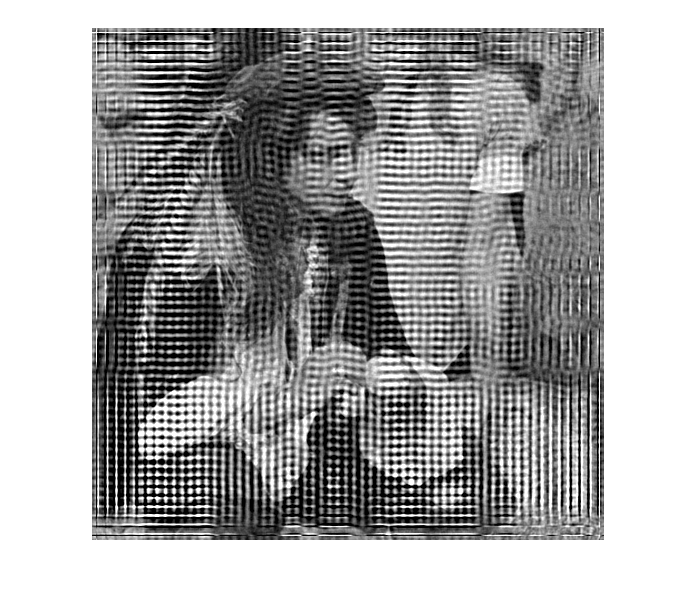

load BlurKernel.mat
blur_pic = imread('man_disk_blurred.png');
fixed_pic = deconvreg(blur_pic,kernel);
original_pic = imread('man.png');
PSNR = psnr(fixed_pic, original_pic)

# mandelbrot.m

function mandelbrot(n,niter,xs,ys,g)
% Draw a Mandelbrot set.
% n: resolution
% niter: maximum iteration number
% xs,ys: centor of the window
% g: 2*g is the width and the height of the window
x0 = xs-g; x1 = xs+g;
y0 = ys-g; y1 = ys+g;
[x,y] = meshgrid(linspace(x0,x1,n),linspace(y0,y1,n));
c = x+1i*y;
z = zeros(size(c));
k = zeros(size(c));
for ii = 1:niter
    z = z.^2+c;
    k(abs(z)>2&k==0) = niter-ii;
end
figure,
set(gcf,'position',[100 100 1024 1024])
imagesc(k),
colormap cool
axis square
axis off
end